cancer = readtable("..\datasets\breastcancer.csv");

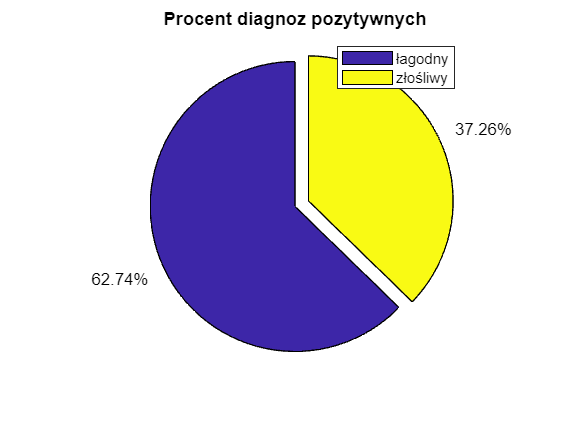

figure(1);
diagnosis_counts = groupcounts(cancer.diagnosis);
labels = {'łagodny', 'złośliwy'};
explode = [0 1];
pie(diagnosis_counts, explode, '%.2f%%');
title('Procent diagnoz pozytywnych');
legend(labels);

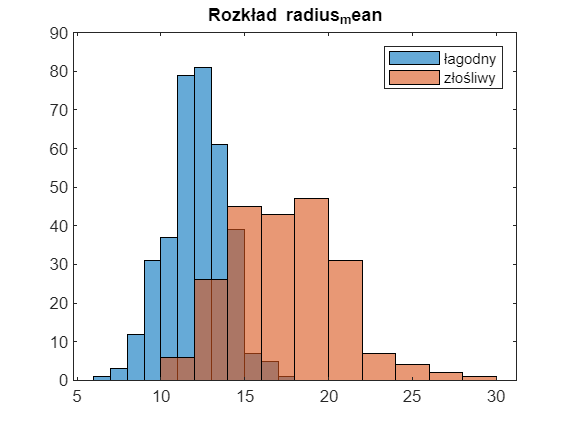

figure(2);

attr = "radius_mean";
values_where_B = cancer.(attr)(cancer.diagnosis == "B");
values_where_M = cancer.(attr)(cancer.diagnosis == "M");

histogram(values_where_B);
hold on;
histogram(values_where_M);
hold off;
title("Rozkład " + attr);
legend(labels);

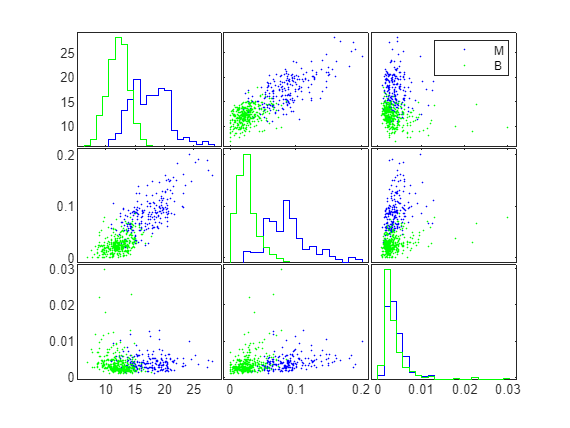

figure(3);
X = [cancer.radius_mean cancer.concave_points_mean cancer.fractal_dimension_se];
% Statistics and Machine Learning Toolbox required
gplotmatrix(X, [], cancer.diagnosis);